clear ; close all ; clc
syms s I B K tau

P = 1/ (I*s + B)

$$P = \frac{1}{B+\text{I}\,s}$$

[N,D] = numden(P);
P = (N/B) / expand((D/B))

$$P = \frac{1}{B\,\left(\frac{\text{I}\,s}{B}+1\right)}$$


Inum = 1;
% Bnum = 0.1:0.5:10;
Bnum = logspace(-1, 1.2, 10)

Bnum =     0.1000    0.1756    0.3082    0.5412    0.9501    1.6681    2.9286    5.1418    9.0273   15.8489


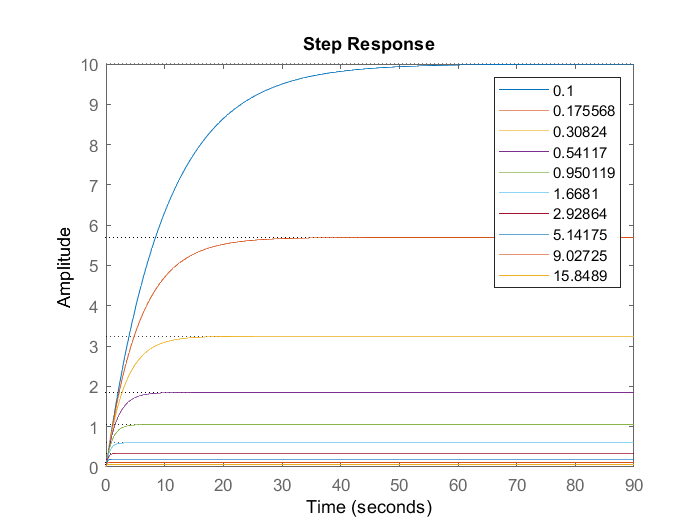

nb = length(Bnum);
figure (100) ; clf ; hold on
for b = 1:nb
    Pnum = subs(P, [I B], [Inum Bnum(b)]);
    Ptf = sym2tf(Pnum);
    [sys.A,sys.B,sys.C,sys.D] = tf2ss(Ptf.num{1}, Ptf.den{1});
    Pss = ss(sys.A,sys.B,sys.C,sys.D);
    %initial(Pss, 1)
    step(Pss)
end
legend(string(Bnum))